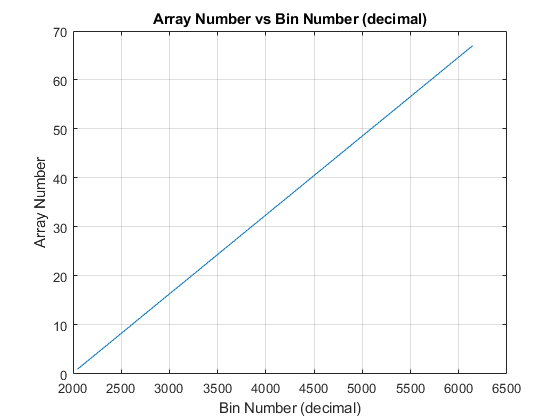

clear;
close all;

% 3 Vpp w/ 1.65 V DC Offset Range
voltage_range = [1.65:0.05:4.95];

bin = Voltage2Bin(voltage_range,voltage_range(1),voltage_range(end),12);

% Plot
figure();
plot(bin,1:length(bin))
grid on;
xlabel('Bin Number (decimal)')
ylabel('Array Number')
title('Array Number vs Bin Number (decimal)')

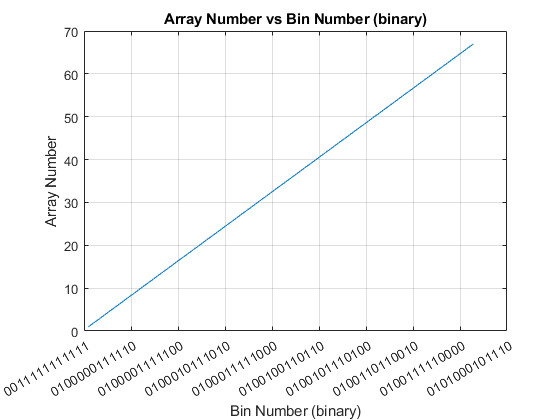


% Convert to Binary and Plot
bins2binary = dec2bin(bin);

figure();
plot(bin,1:length(bin))
grid on;
xticklabels(bins2binary)
xlabel('Bin Number (binary)')
ylabel('Array Number')
title('Array Number vs Bin Number (binary)')

function [bin] = Voltage2Bin(voltage,min_voltage,max_voltage,bits)

% Voltage Range
range = max_voltage - min_voltage;

% Number of Levels
levels = 2^bits;

% Least Significant Bit
LSB = range/levels;

bin = floor(voltage/LSB);

end